f= @(x) 4./(1+x.^2);
I = integral(f,0,1);

T_vals=[];
M_vals=[];

for n=1:200
    T_vals(end+1)=Trapezoid(f,0,1,n);
    M_vals(end+1)=Midpoint(f,0,1,n);
end

err_trape=abs(T_vals-I)

err_trape =      1.415926535897931e-01     4.159265358979303e-02     1.851573051287048e-02     1.041618300155767e-02     6.666539778803049e-03     4.629587118529344e-03     3.401343682765567e-03     2.604159098704262e-03     2.057609435510699e-03     1.666664682634433e-03     1.377409348367387e-03     1.157406742942513e-03     9.861928828289734e-04     8.503398725450140e-04     7.407405665533773e-04     6.510415484042298e-04     5.767011865422944e-04     5.144032338466609e-04     4.616804749075776e-04     4.166666356644200e-04     3.779289262233476e-04     3.443525995798780e-04     3.150598479706446e-04     2.893518414683882e-04     2.666666585393607e-04     2.465483170479565e-04     2.286236802926389e-04     2.125850298968501e-04     1.981767703469473e-04     1.851851824627992e-04     1.734304521532337e-04     1.627604148182193e-04     1.530456060550023e-04     1.441753159010517e-04     1.360544206892023e-04     1.286008221335067e-04     1.217433642128896e-04     1.154201286119871e-04

err_mid=abs(M_vals-I)

err_mid =      5.840734641020706e-02     2.076028758667725e-02     9.256556275810457e-03     5.207864804149587e-03     3.333210413534626e-03     2.314773632644762e-03     1.700663937674651e-03     1.302076001895802e-03     1.028802967819598e-03     8.333314113055934e-04     6.887041492080748e-04     5.787030600044041e-04     4.930962487317281e-04     4.251698127530901e-04     3.703702016251142e-04     3.255207187669029e-04     2.883505547393028e-04     2.572015895787594e-04     2.308402176849356e-04     2.083333033011669e-04     1.889644522674594e-04     1.721762915871672e-04     1.575299177027922e-04     1.446759158678645e-04     1.333333254596170e-04     1.232741555137196e-04     1.143118377462393e-04     1.062925130179693e-04     9.908838360939143e-05     9.259258995530928e-05     8.671522502856632e-05     8.138020654424594e-05     7.652280230807662e-05     7.208765734967315e-05     6.802720983856148e-05     6.430041064042769e-05     6.087168174451207e-05     5.771006399690748e-05  

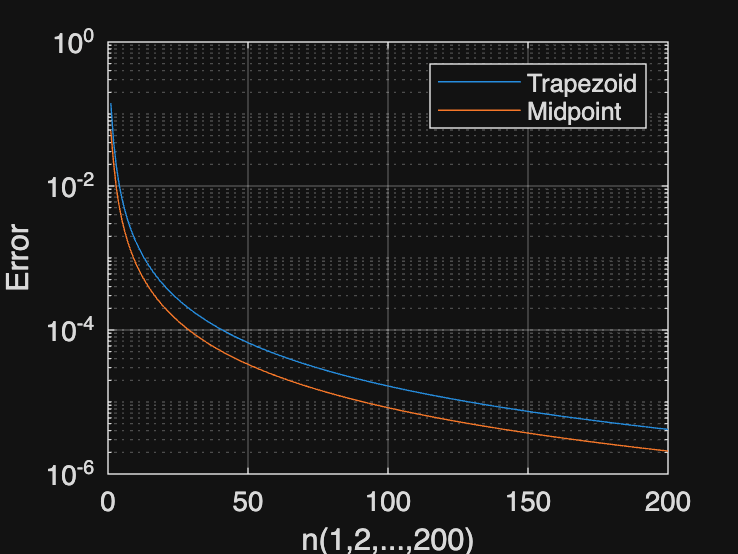


semilogy(1:200,err_trape,'DisplayName','Trapezoid');
hold on;
semilogy(1:200,err_mid,'DisplayName','Midpoint');
hold off;
xlabel("n(1,2,...,200)");
ylabel("Error");
legend("show");

%Composite Trapezoid rule

function T= Trapezoid(f,a,b,n)
    h=(b-a)/n;
    x=a+h.*(0:n);
    y=f(x);
    T=h*(sum(y(2:n))+0.5*(y(1)+y(n+1)));
end

%Composite midpoint rule
function M= Midpoint(f,a,b,n);
    h=(b-a)/n;
    x_mid=a+h.*(0.5:1:n-0.5);
    M=h*sum(f(x_mid));
end
